# ARIMA - 예상 시점을 다른 걸로 다시 테스트 필요

이것을 

- % 마지막 두개로

- yf0 = cap_05(idx_change_before_vec(end - 1:end));

이것으로  

- % 마지막 두개 + 새로운 것 10개

- yf0 = [ cap_05(idx_change_before_vec(end - 1:end)) cap_05(idx_change_before_vec(1:10) ];

# 저장된 데이타를 모두 읽어들인다.

clear
load ryan_gen_data

% https://people.duke.edu/~rnau/arimrule.htm
% https://github.com/KevinChngJY/timeseriesinmatlab

% https://kr.mathworks.com/help/econ/specify-ar-models.html
xCcTimeSec_05 = regression_vector_05(:,1);
xCcTimeSec_05 = xCcTimeSec_05./1200 ; % sec to hour

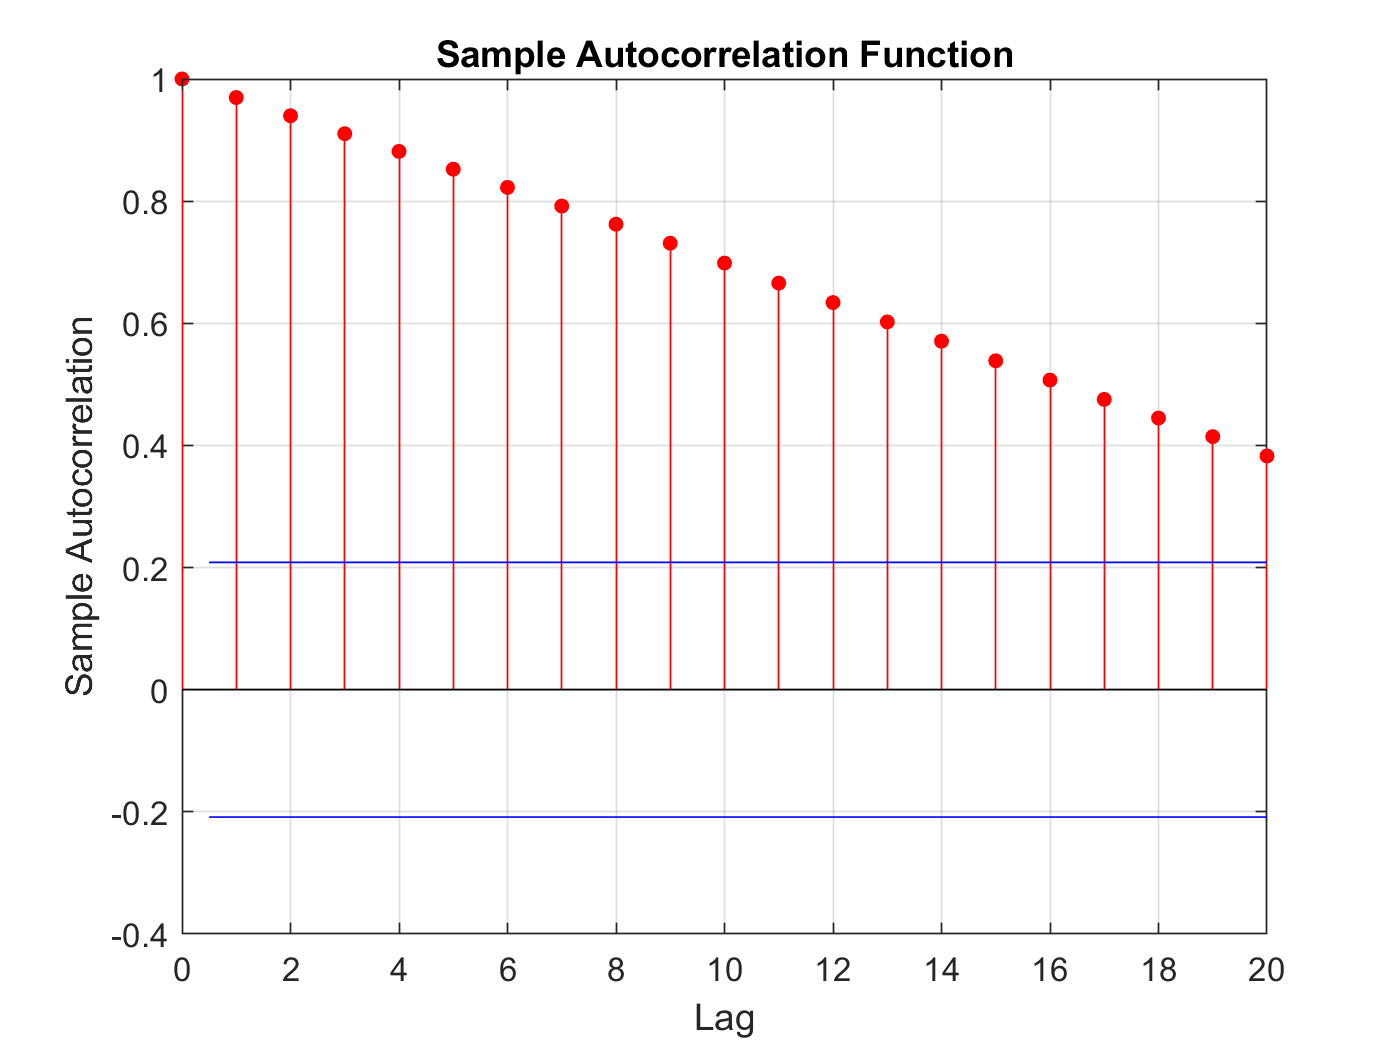

figure
autocorr(cap_05)

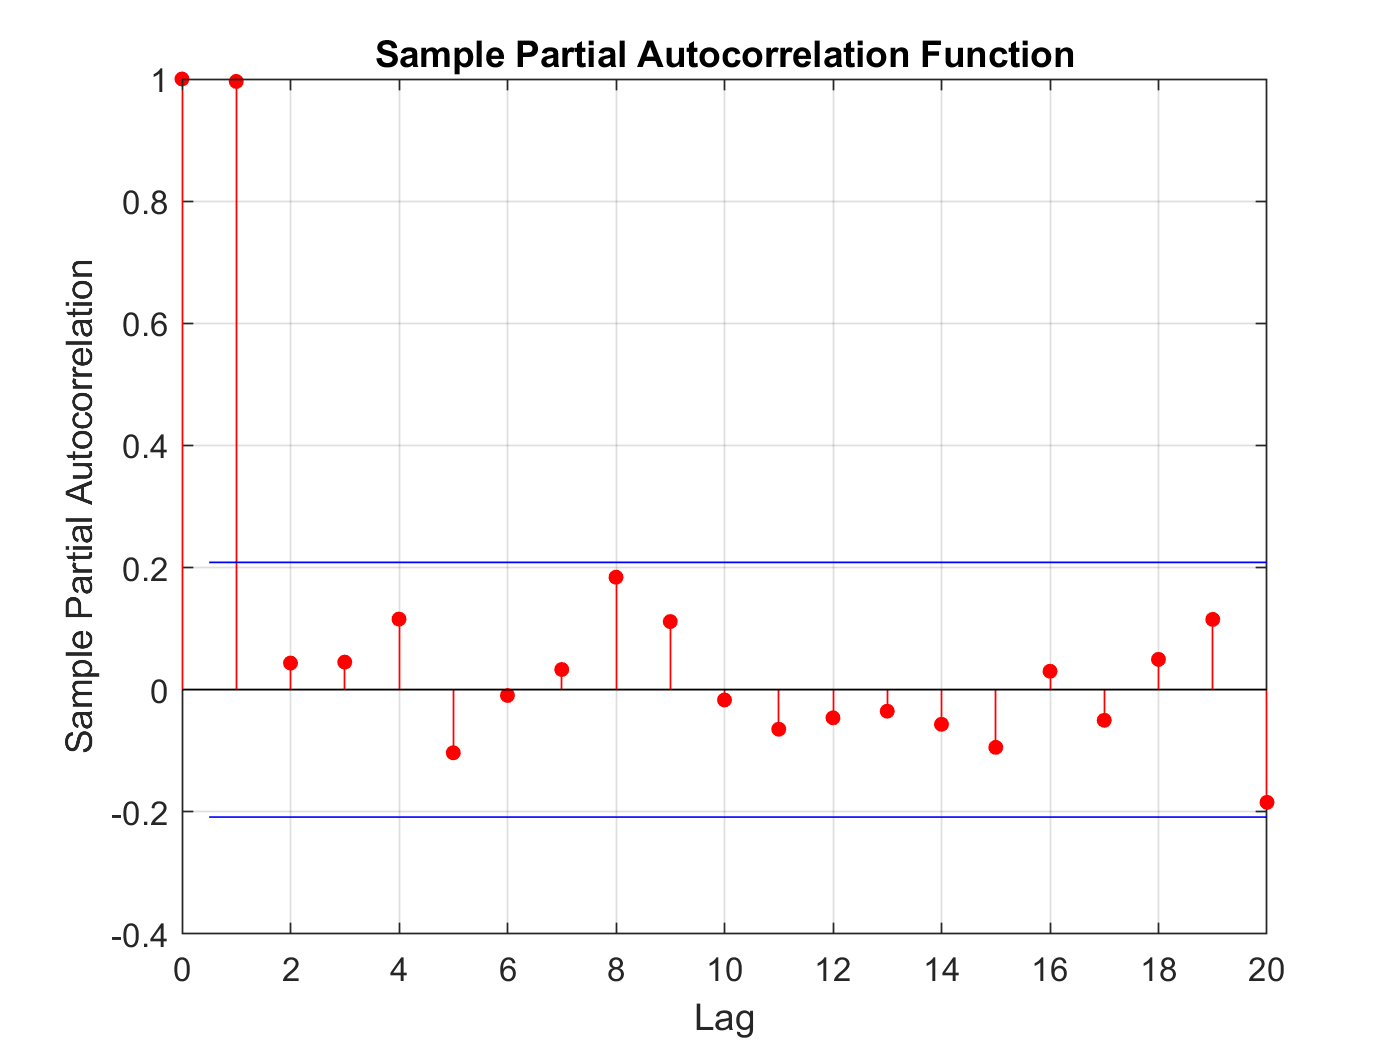

figure
parcorr(cap_05)


acf = autocorr(cap_05,'NumLags',15)

acf =     1.0000
    0.9697
    0.9398
    0.9104
    0.8815
    0.8523
    0.8225
    0.7920
    0.7622
    0.7312


pacf = parcorr(cap_05,'NumLags',15)

pacf =     1.0000
    0.9960
    0.0437
    0.0451
    0.1156
   -0.1033
   -0.0094
    0.0331
    0.1842
    0.1116


[length(acf) length(pacf)]

ans =     16    16


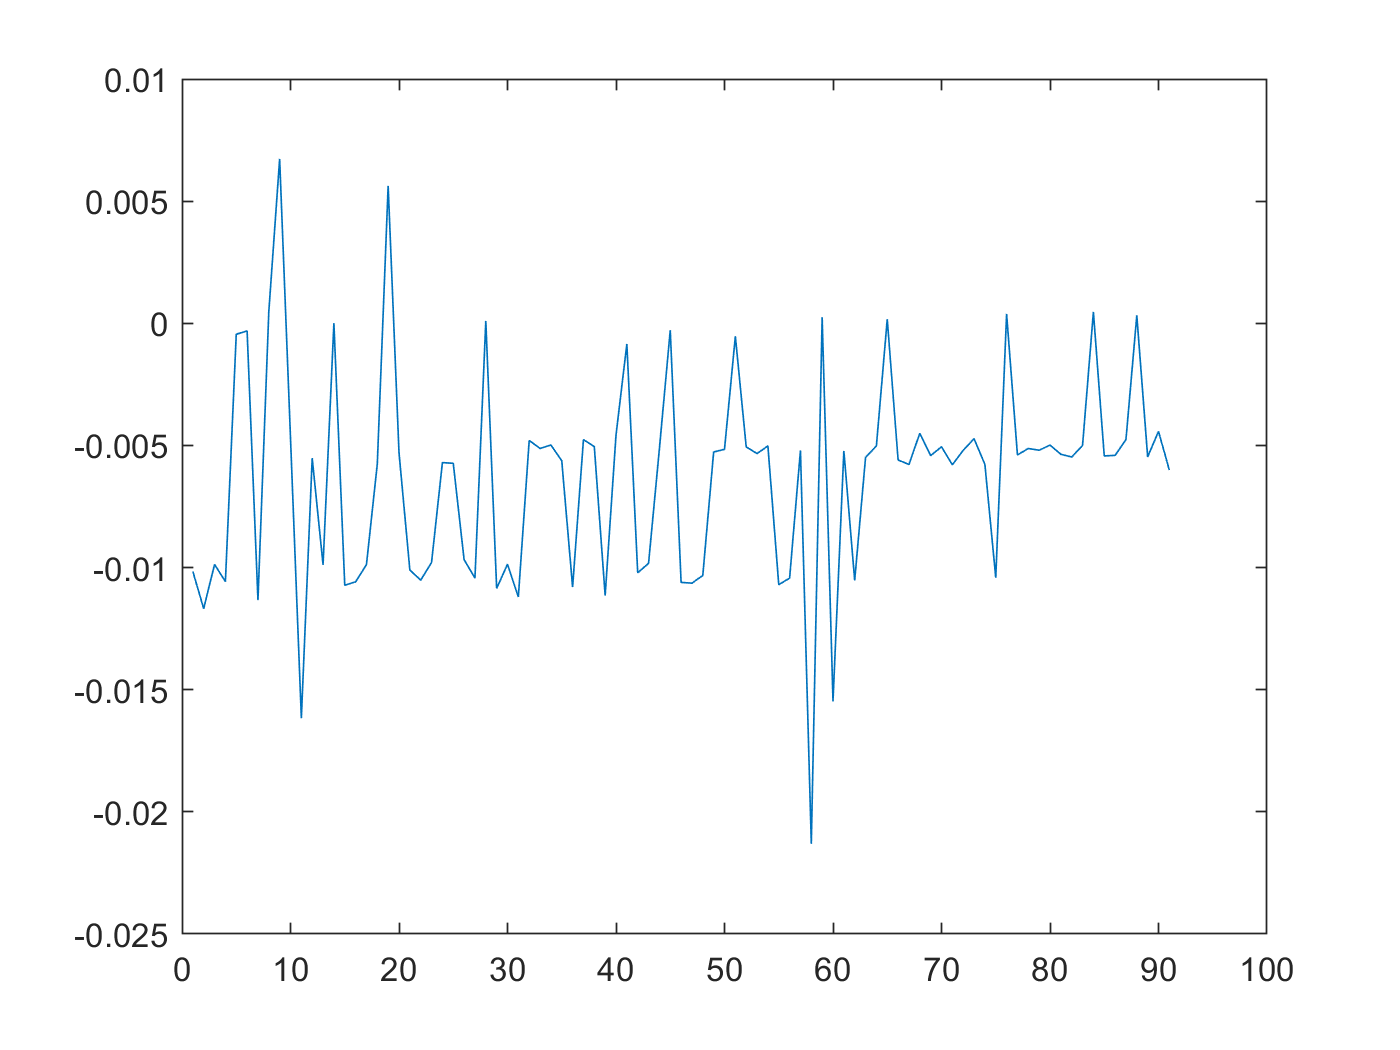


% https://kr.mathworks.com/help/econ/box-jenkins-differencing-vs-arima-estimation.html
%YDiff5 = cap_05(2:end) - cap_05(1:end-1);
YDiff5 = diff(cap_05);

figure 
plot(YDiff5)

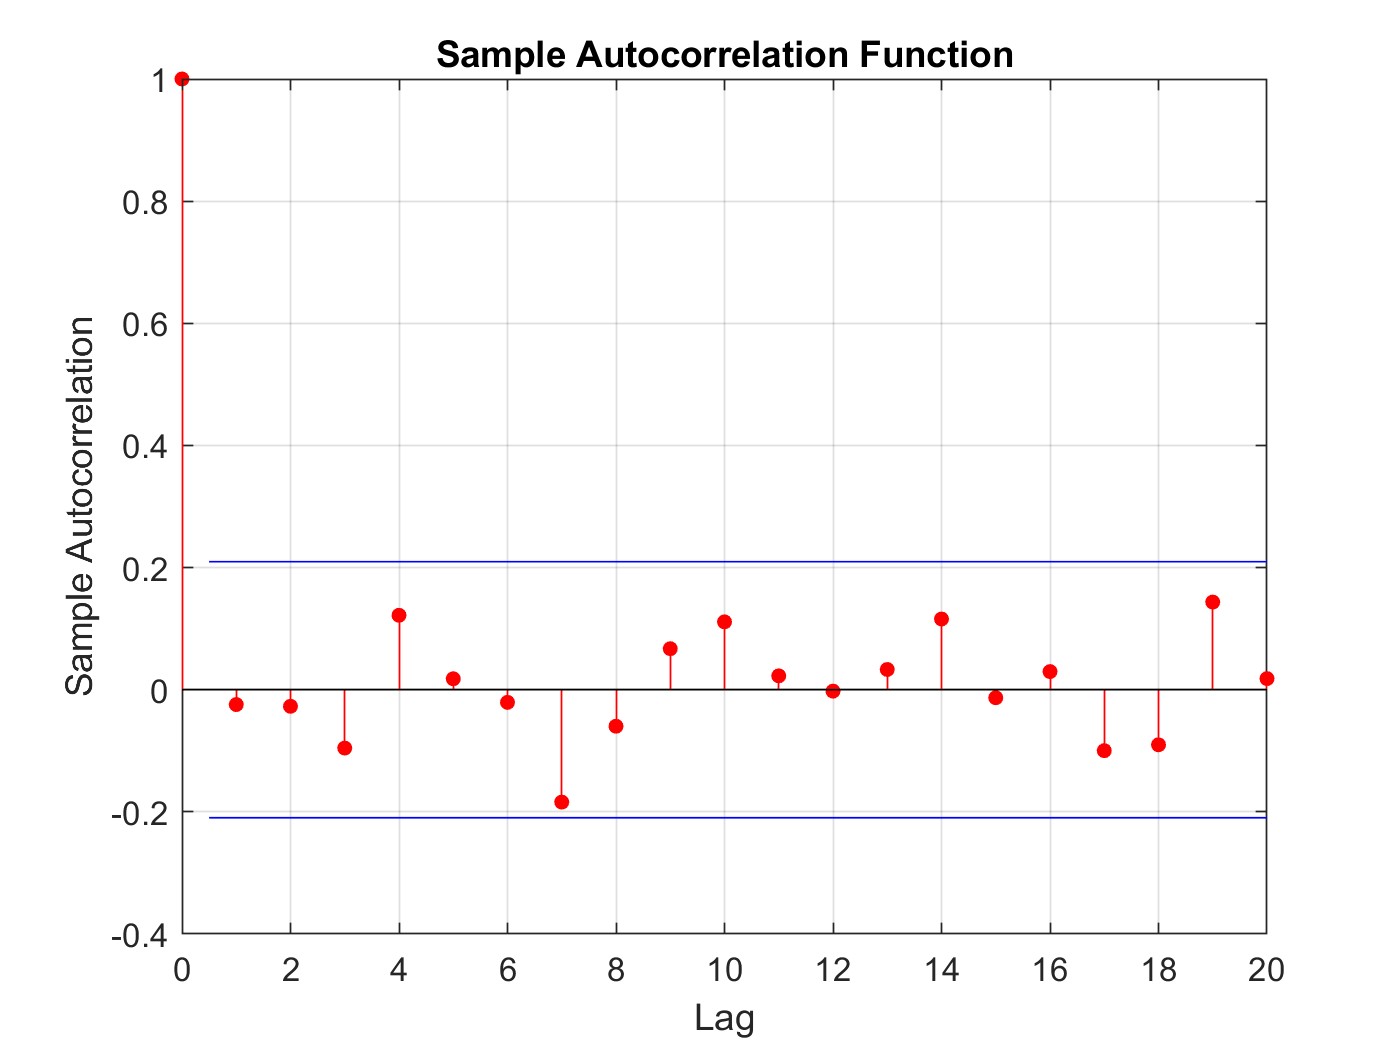

figure
autocorr(YDiff5)

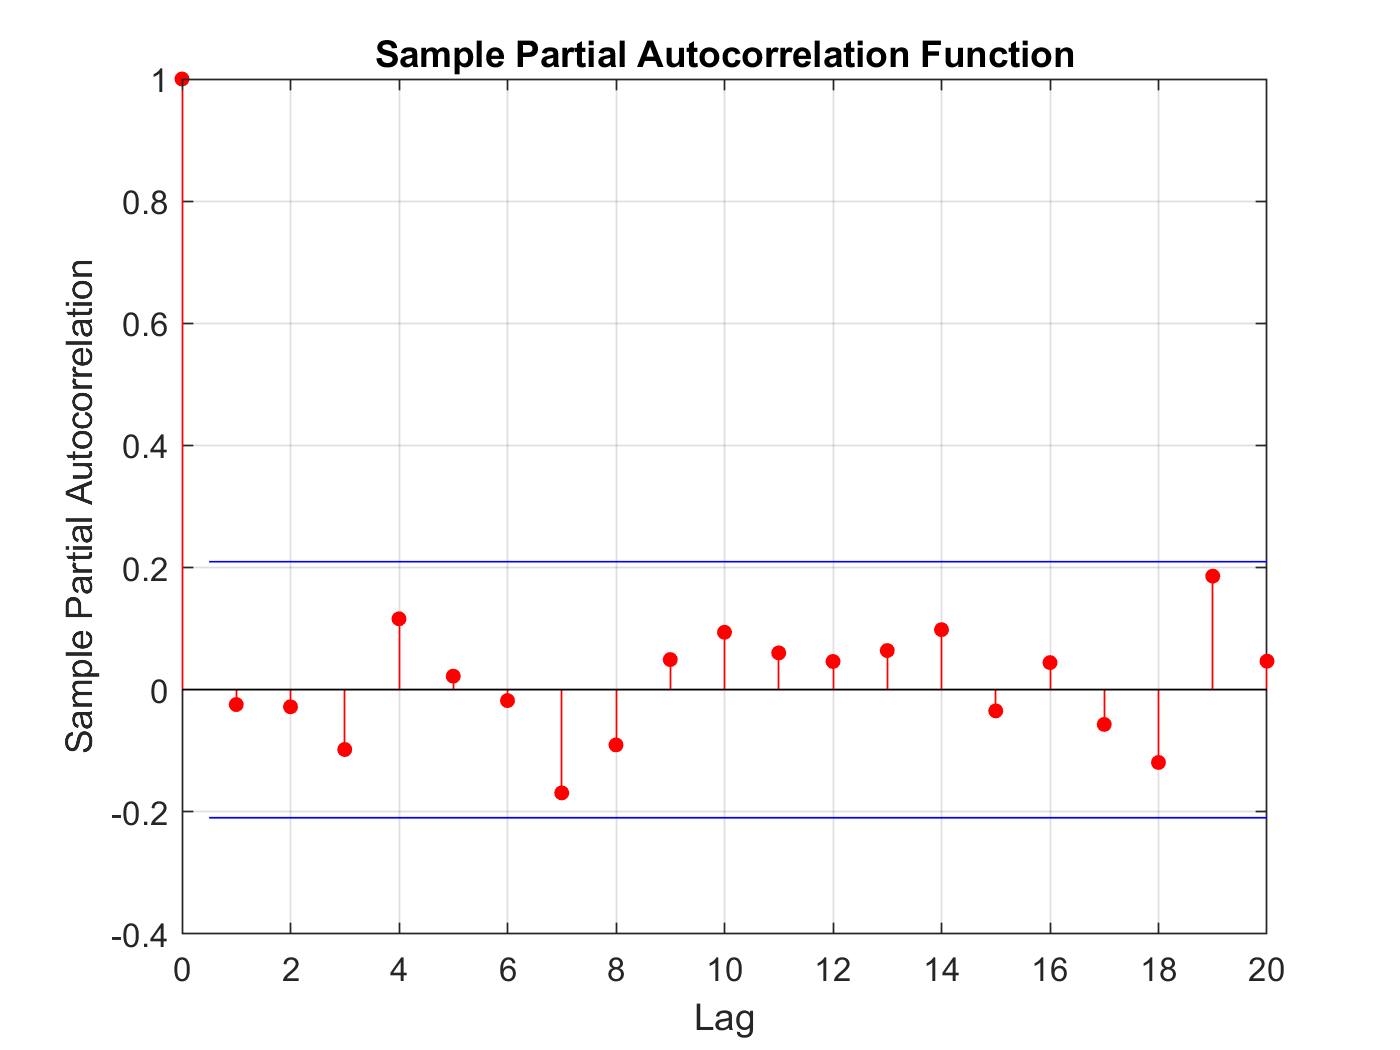

figure
parcorr(YDiff5)

# Estimate #05 Capacity by #05 ARIMA(0,1,0)

training = all 

estimating = all 

end_index = length(cap_05);
idx_change_before_vec = [1:(idx_0506_change-1)];
idx_change_vec = [idx_0506_change:end_index];
change_length = length(idx_change_vec);

% ARIMA 모델에 적당하다. PCF Die out PACF Die out 
Mdl = arima(0,1,0);  % 0 1 0
%Mdl = arima(0,1,3);
EstMdl = estimate(Mdl,cap_05,'Y0',cap_05);

 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    3.9555e-05       0.29011       0.00013634       0.99989
    Variance       0.16286      0.034722           4.6904    2.7265e-06



EstMdl

EstMdl =   arima with properties:

     Description: "ARIMA(0,1,0) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 1
               D: 1
               Q: 0
        Constant: 3.95551e-05
              AR: {}
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 0.162861

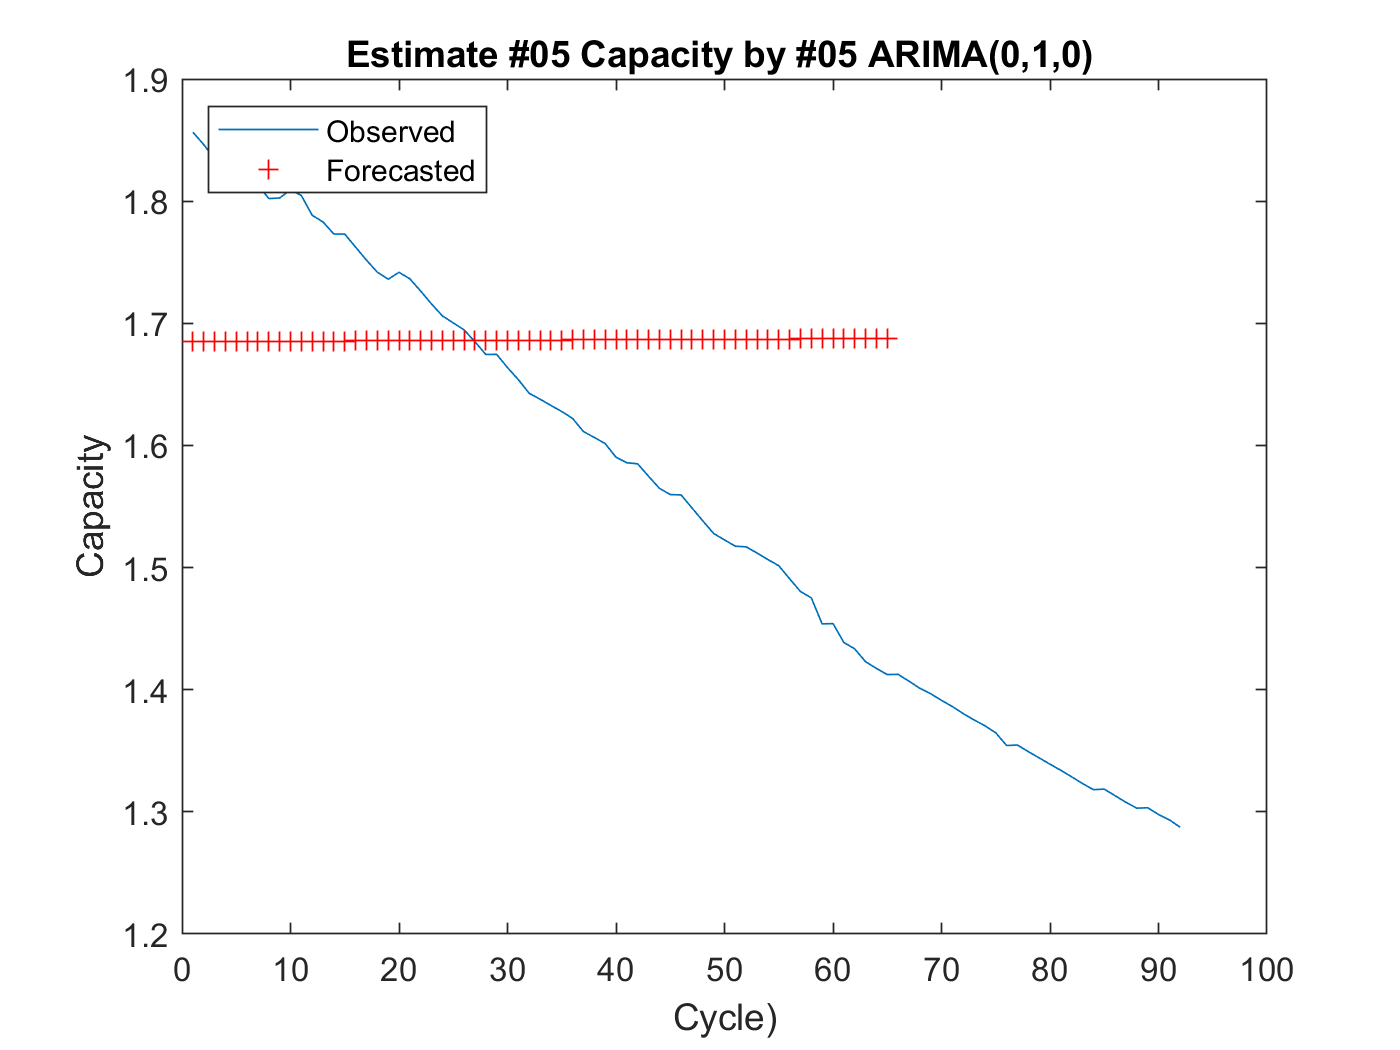

%compare(cap_05,EstMdl,5)

% 이전것 전체로
yf0 = cap_05(idx_change_before_vec(1:end));
yf = forecast(EstMdl,change_length,yf0);
%Plot the first xxx observations and the forecasts.

figure
h1 = plot(cap_05);
hold on
h2 = plot([1:length(yf)],yf,'r+');
%h2 = plot([cap_05(1:idx_change_vec);yf])
legend([h1 h2],"Observed","Forecasted",...
	     'Location',"NorthWest")
title("Estimate #05 Capacity by #05 ARIMA(0,1,0) ")
xlabel("Cycle)")
ylabel("Capacity")
hold off

# Estimate #05 Capacity by #05 ARIMA(0,1,0)

training = all before

estimating = all after

end_index = length(cap_05);
idx_change_before_vec = [1:(idx_0506_change-1)];
idx_change_vec = [idx_0506_change:end_index];
change_length = length(idx_change_vec);

% ARIMA 모델에 적당하다. PCF Die out PACF Die out 
Mdl = arima(0,1,0);  % 0 1 0
%Mdl = arima(0,1,3);
EstMdl = estimate(Mdl,cap_05(idx_change_vec),...
    'Y0',cap_05(idx_change_before_vec));

 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    -0.0061576     0.00054216       -11.357      6.8085e-30
    Variance    1.5405e-05     1.7503e-06        8.8011      1.3542e-18



EstMdl

EstMdl =   arima with properties:

     Description: "ARIMA(0,1,0) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 1
               D: 1
               Q: 0
        Constant: -0.00615759
              AR: {}
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 1.54046e-05

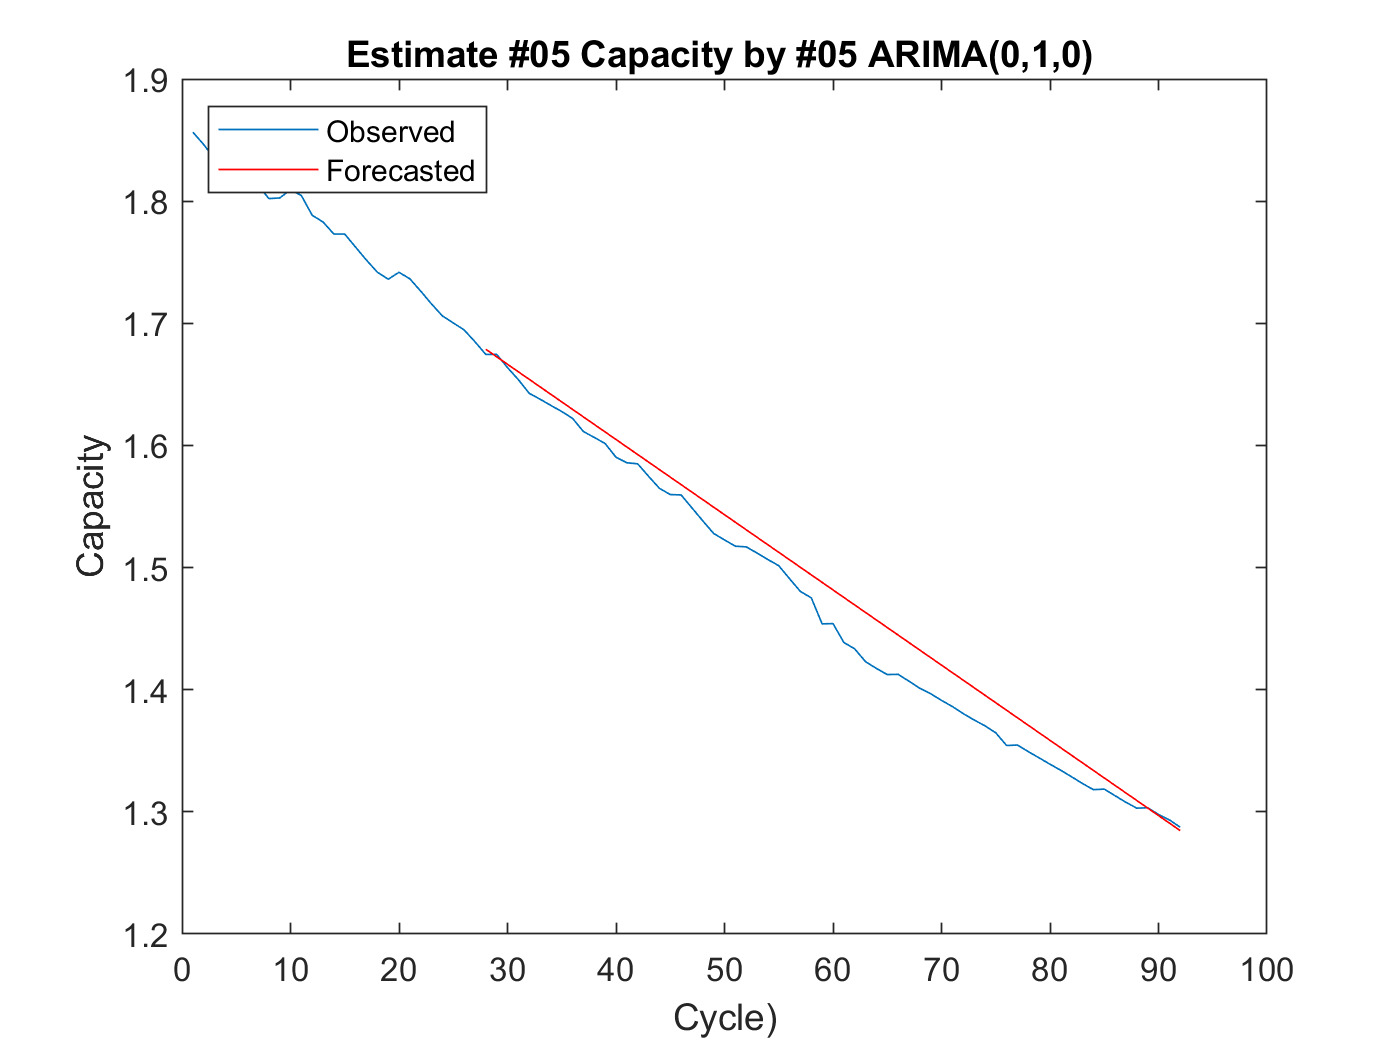


% 이전것 전체로
yf0 = cap_05(idx_change_before_vec(1:end));
yf = forecast(EstMdl,change_length,yf0);
%Plot the first xxx observations and the forecasts.

figure
h1 = plot(cap_05);
hold on
h2 = plot([(idx_0506_change):end_index],yf,'r');
%h2 = plot([cap_05(1:idx_change_vec);yf])
legend([h1 h2],"Observed","Forecasted",...
	     'Location',"NorthWest")
title("Estimate #05 Capacity by #05 ARIMA(0,1,0) ")
xlabel("Cycle)")
ylabel("Capacity")
hold off

# Estimate #05 Capacity by #05 ARIMA(0,1,0) with Window(2,10)

training = all before

estimating = all after

end_index = length(cap_05);
idx_change_before_vec = [1:(idx_0506_change-1)];
idx_change_vec = [idx_0506_change:end_index];
change_length = length(idx_change_vec);

% ARIMA 모델에 적당하다. PCF Die out PACF Die out 
Mdl = arima(0,1,0);  % 0 1 0
%Mdl = arima(0,1,3);
EstMdl = estimate(Mdl,cap_05(idx_change_vec),...
    'Y0',cap_05(idx_change_before_vec));

 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    -0.0061576     0.00054216       -11.357      6.8085e-30
    Variance    1.5405e-05     1.7503e-06        8.8011      1.3542e-18



EstMdl

EstMdl =   arima with properties:

     Description: "ARIMA(0,1,0) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 1
               D: 1
               Q: 0
        Constant: -0.00615759
              AR: {}
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 1.54046e-05

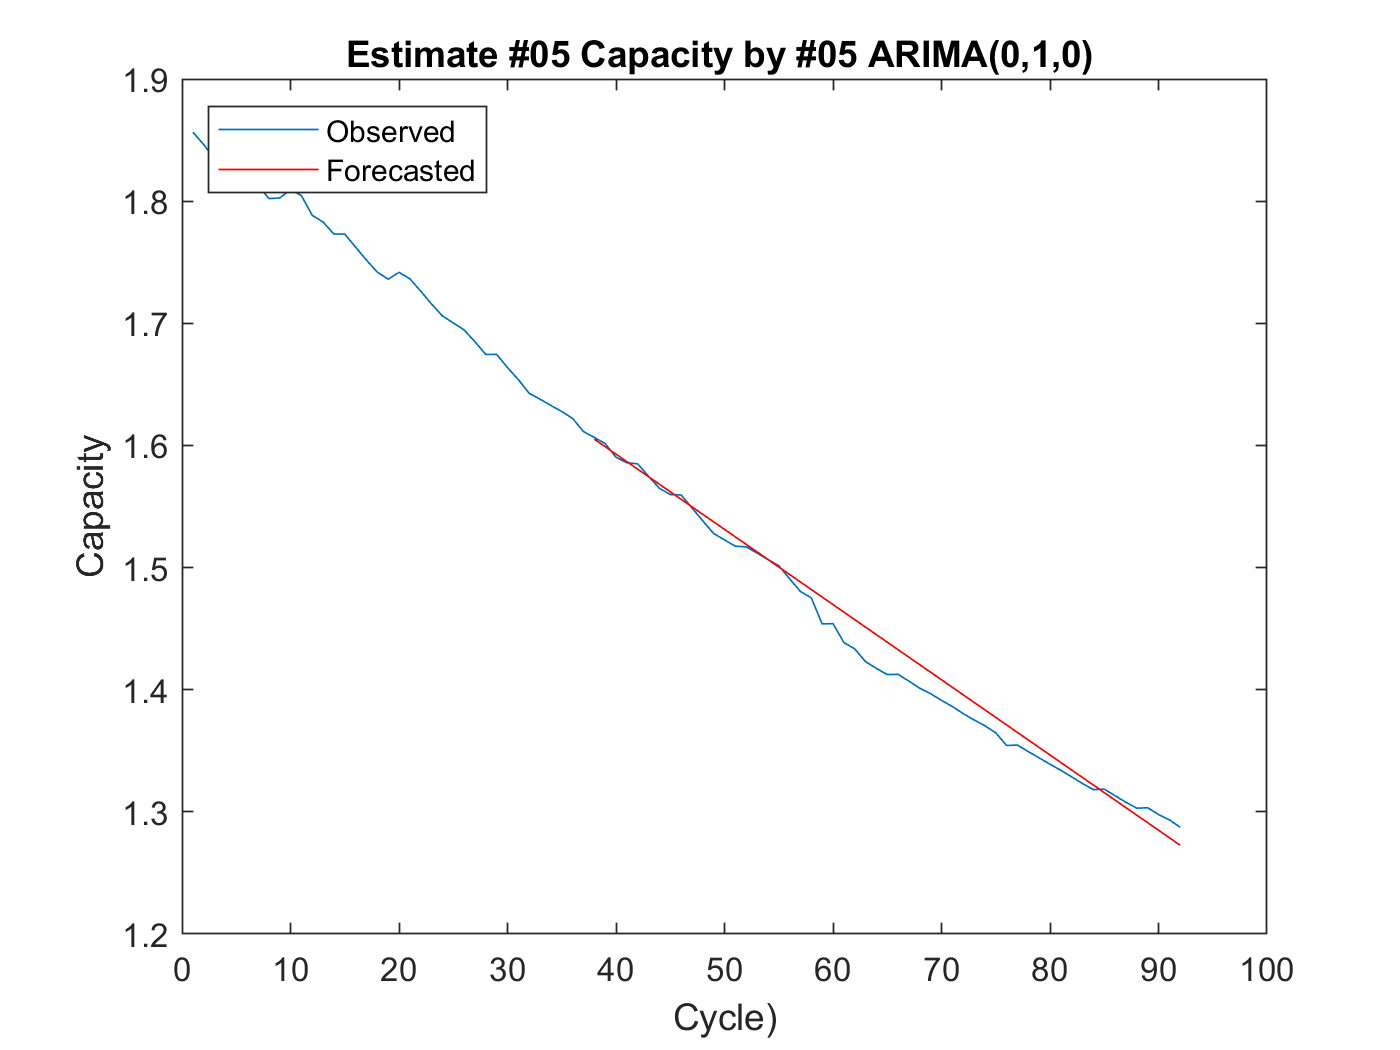

window_after_length = 10;
window_before_length = 2;
estimate_length=window_before_length + window_after_length;
predict_length = change_length - window_after_length;
yf0 = [ cap_05(idx_change_before_vec(end - window_before_length:end)) ; cap_05(idx_change_vec(1:window_after_length))];
% 이전것 전체로
% yf0 = cap_05(idx_change_before_vec(1:end));

yf = forecast(EstMdl,predict_length,yf0);
%Plot the first xxx observations and the forecasts.

figure
h1 = plot(cap_05);
hold on
h2 = plot([(idx_0506_change+window_after_length):end_index],yf,'r');
%h2 = plot([cap_05(1:idx_change_vec);yf])
legend([h1 h2],"Observed","Forecasted",...
	     'Location',"NorthWest")
title("Estimate #05 Capacity by #05 ARIMA(0,1,0) ")
xlabel("Cycle)")
ylabel("Capacity")
hold off

# Estimate #05 Capacity by #05 ARIMA(0,1,0)

training = all before + all after

estimating = all after

end_index = length(cap_05);
idx_change_before_vec = [1:(idx_0506_change-1)];
idx_change_vec = [idx_0506_change:end_index];
change_length = length(idx_change_vec);

% ARIMA 모델에 적당하다. PCF Die out PACF Die out 
Mdl = arima(0,1,0);  % 0 1 0
%Mdl = arima(0,1,3);
EstMdl = estimate(Mdl,cap_05(idx_change_vec),...
    'Y0',cap_05(1:end_index)); % <================

 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    4.8668e-05       0.29533       0.00016479       0.99987
    Variance         0.114       0.02888           3.9476    7.8951e-05



EstMdl

EstMdl =   arima with properties:

     Description: "ARIMA(0,1,0) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 1
               D: 1
               Q: 0
        Constant: 4.86675e-05
              AR: {}
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 0.114004

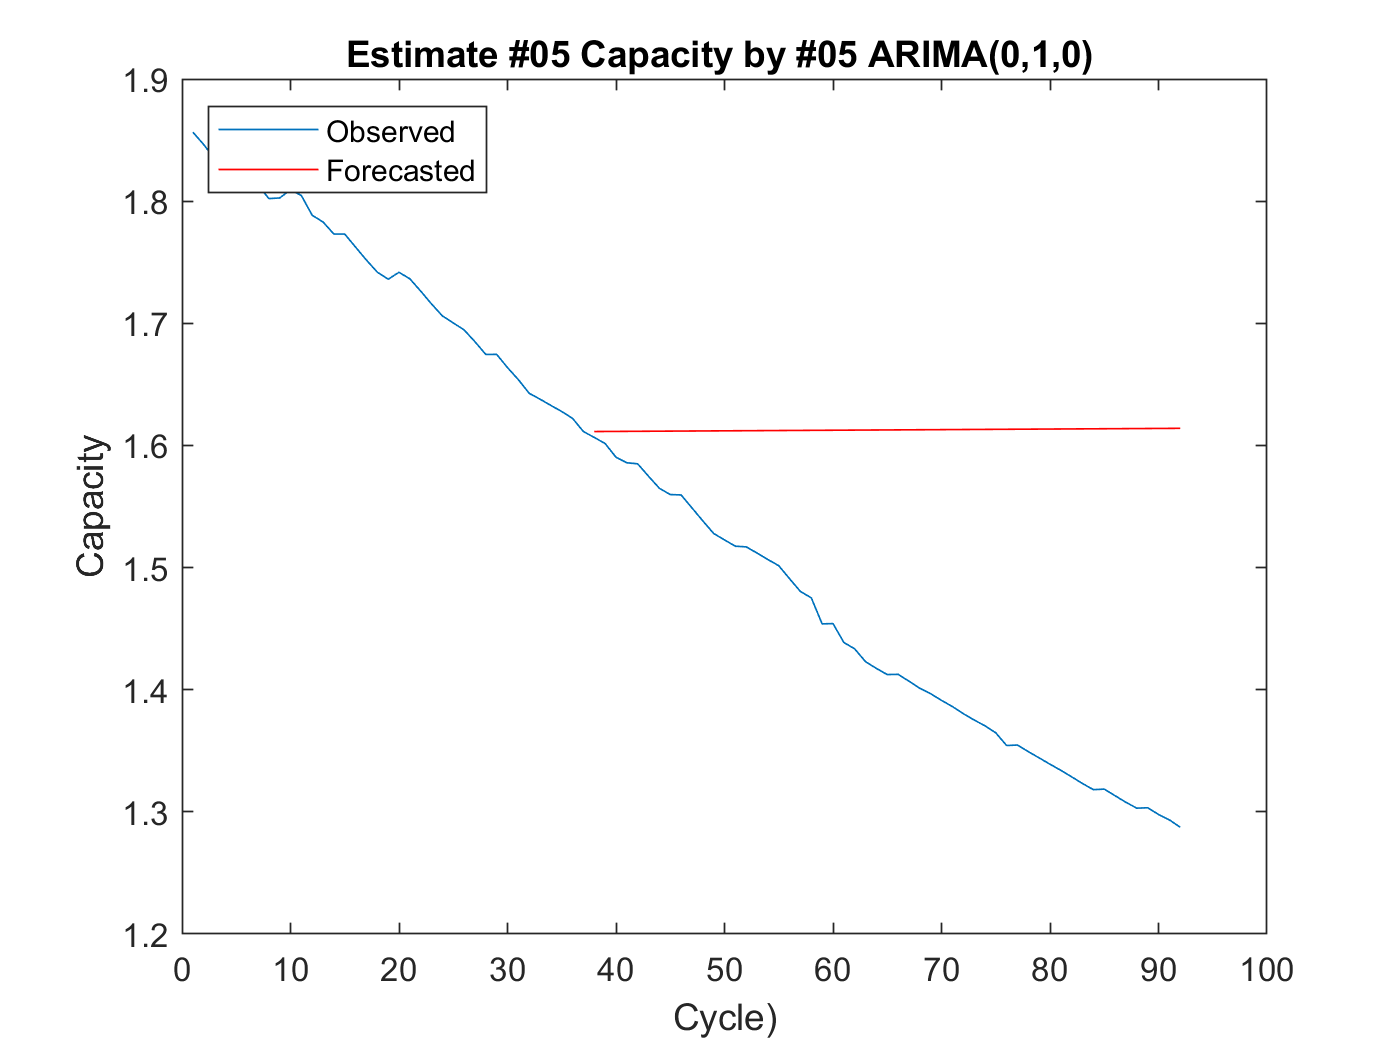

window_after_length = 10;
window_before_length = 2;
estimate_length=window_before_length + window_after_length;
predict_length = change_length - window_after_length;
yf0 = [ cap_05(idx_change_before_vec(end - window_before_length:end)) ; cap_05(idx_change_vec(1:window_after_length))];
% 이전것 전체로
% yf0 = cap_05(idx_change_before_vec(1:end));

yf = forecast(EstMdl,predict_length,yf0);
%Plot the first xxx observations and the forecasts.

figure
h1 = plot(cap_05);
hold on
h2 = plot([(idx_0506_change+window_after_length):end_index],yf,'r');
%h2 = plot([cap_05(1:idx_change_vec);yf])
legend([h1 h2],"Observed","Forecasted",...
	     'Location',"NorthWest")
title("Estimate #05 Capacity by #05 ARIMA(0,1,0) ")
xlabel("Cycle)")
ylabel("Capacity")
hold off

# Find Best ARIMA p,d,q value 

% p,q => max 3 
% to avoid this message
% The error message “the non-seasonal autoregressive polynomial is unstable” 
% https://kr.mathworks.com/matlabcentral/answers/261576-the-non-seasonal-moving-average-polynomial-is-non-invertible

[minP,minQ,minBIC,BIC]=checkArima_v2(cap_05,1,3,3)

minP = 2

minQ = 2

minBIC = -724.7554

BIC =  -722.2795 -717.7998 -713.4389
 -718.3285 -724.7554 -720.1612
 -714.7093 -720.1818 -715.3351


cap_05_pdq=[ minP, 1, minQ ]

cap_05_pdq =      2     1     2


cap_05_pdq_string = sprintf('%d,' , cap_05_pdq);
cap_05_pdq_string = cap_05_pdq_string(1:end-1)% strip final comma

cap_05_pdq_string = '2,1,2'

[minP,minQ,minBIC,BIC]=checkArima_v2(cap_05,2,3,3)

minP = 1

minQ = 1

minBIC = -718.3263

BIC =  -718.3263 -717.3229 -712.7333
 -713.7223 -713.6218 -708.1408
 -705.0902 -709.0197 -710.0904


[minP,minQ,minBIC,BIC]=checkArima_v2(cap_06,1,3,3)

minP = 3

minQ = 2

minBIC = -857.3249

BIC =  -838.3193 -852.0439 -853.5284
 -842.8156 -851.8478 -849.1545
 -844.1552 -857.3249 -851.1524


cap_06_pdq=[ minP, 1, minQ ]

cap_06_pdq =      3     1     2


cap_06_pdq_string = sprintf('%d,' , cap_06_pdq);
cap_06_pdq_string = cap_06_pdq_string(1:end-1)% strip final comma

cap_06_pdq_string = '3,1,2'

[minP,minQ,minBIC,BIC]=checkArima_v2(cap_06,2,3,3)

minP = 2

minQ = 2

minBIC = -860.0792

BIC =  -846.7771 -856.2269 -853.7029
 -848.6873 -860.0792 -853.5821
 -844.3363 -855.8252 -852.7296


[minP,minQ,minBIC,BIC]=checkArima_v2(cap_0506,1,3,3)

minP = 3

minQ = 2

minBIC = -814.5362

BIC =  -813.8205 -809.2999 -805.3553
 -809.6146 -814.2481 -811.2420
 -805.0634 -814.5362 -806.4237


cap_0506_pdq=[ minP, 1, minQ ]

cap_0506_pdq =      3     1     2


cap_0506_pdq_string = sprintf('%d,' , cap_0506_pdq);
cap_0506_pdq_string = cap_0506_pdq_string(1:end-1)% strip final comma

cap_0506_pdq_string = '3,1,2'

[minP,minQ,minBIC,BIC]=checkArima_v2(cap_0506,2,3,3)

minP = 1

minQ = 1

minBIC = -809.9669

BIC =  -809.9669 -807.7756 -803.8899
 -806.6289 -804.5964 -796.9161
 -802.5654 -800.0014 -802.0435


[minP,minQ,minBIC,BIC]=checkArima_v2(cap_0605,1,3,3)

minP = 2

minQ = 1

minBIC = -754.8238

BIC =  -752.7218 -753.7283 -738.5870
 -754.8238 -750.2187 -747.7608
 -750.6816 -749.2636 -745.5525


cap_0605_pdq=[ minP, 1, minQ ]

cap_0605_pdq =      2     1     1


cap_0605_pdq_string = sprintf('%d,' , cap_0605_pdq);
cap_0605_pdq_string = cap_0605_pdq_string(1:end-1)% strip final comma

cap_0605_pdq_string = '2,1,1'

[minP,minQ,minBIC,BIC]=checkArima_v2(cap_0605,2,3,3)

minP = 1

minQ = 1

minBIC = -759.4291

BIC =  -759.4291 -754.8240 -752.3660
 -755.2868 -753.7546 -749.8555
 -752.9167 -745.7930 -749.9848


checkArima_v2(cap_05,1,3,3) => 2 2

checkArima_v2(cap_06,1,3,3) => 3 2 

checkArima_v2(cap_0506,1,3,3) => 3 2

checkArima_v2(cap_0605,1,3,3) => 2 1

# Estimate #05 Capacity by #05 ARIMA 

% battery 5 - arima 113

end_index = length(cap_05);
idx_change_before_vec = [ 1:idx_0506_change-1 ];
idx_change_vec = [ idx_0506_change:end_index ] ;
change_length = length(idx_change_vec);

% ARIMA 모델에 적당하다. PCF Die out PACF Die out 
Mdl_05_base = arima(0,1,0);
cap_05_pdq_string

cap_05_pdq_string = '2,1,2'

Mdl_05_opt = arima(2,1,2);  % 0 1 0
%Mdl_05_223 = arima(2,2,3); 

EstMdl_05_base = estimate(Mdl_05_base,cap_05(idx_change_vec),'Y0',cap_05(idx_change_before_vec));

 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    -0.0061576     0.00054216       -11.357      6.8085e-30
    Variance    1.5405e-05     1.7503e-06        8.8011      1.3542e-18



EstMdl_05_opt = estimate(Mdl_05_opt,cap_05(idx_change_vec),'Y0',cap_05(idx_change_before_vec));

 
    ARIMA(2,1,2) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    -0.0060472      0.0056149          -1.077       0.28148
    AR{1}                0         0.6549               0             1
    AR{2}            2e-12        0.47815      4.1828e-12             1
    MA{1}         -0.12826        0.63555        -0.20181       0.84006
    MA{2}          0.19202        0.46563         0.41239       0.68005
    Variance    1.4407e-05     1.8094e-06          7.9626    1.6846e-15



%EstMdl_05_223 = estimate(Mdl_05_223,cap_05(idx_change_vec),'Y0',cap_05(idx_change_before_vec)); % error - Nonseasonal MA polyxx in noninverible

%yf_05_change_before = cap_05(idx_change_before_vec(end - 1:end));
yf_05_change_before = cap_05(idx_change_before_vec(1:end));

yf_05_base = forecast(EstMdl_05_base,change_length,yf_05_change_before);
yf_05_opt = forecast(EstMdl_05_opt,change_length,yf_05_change_before);
%yf223 = forecast(EstMdl_05_223,change_length,yf_05_change_before);

%Plot the first xxx observations and the forecasts.
EstMdl_05_base

EstMdl_05_base =   arima with properties:

     Description: "ARIMA(0,1,0) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 1
               D: 1
               Q: 0
        Constant: -0.00615759
              AR: {}
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 1.54046e-05

EstMdl_05_opt

EstMdl_05_opt =   arima with properties:

     Description: "ARIMA(2,1,2) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 3
               D: 1
               Q: 2
        Constant: -0.00604721
              AR: {2e-12} at lag [2]
             SAR: {}
              MA: {-0.128263 0.192023} at lags [1 2]
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 1.44074e-05

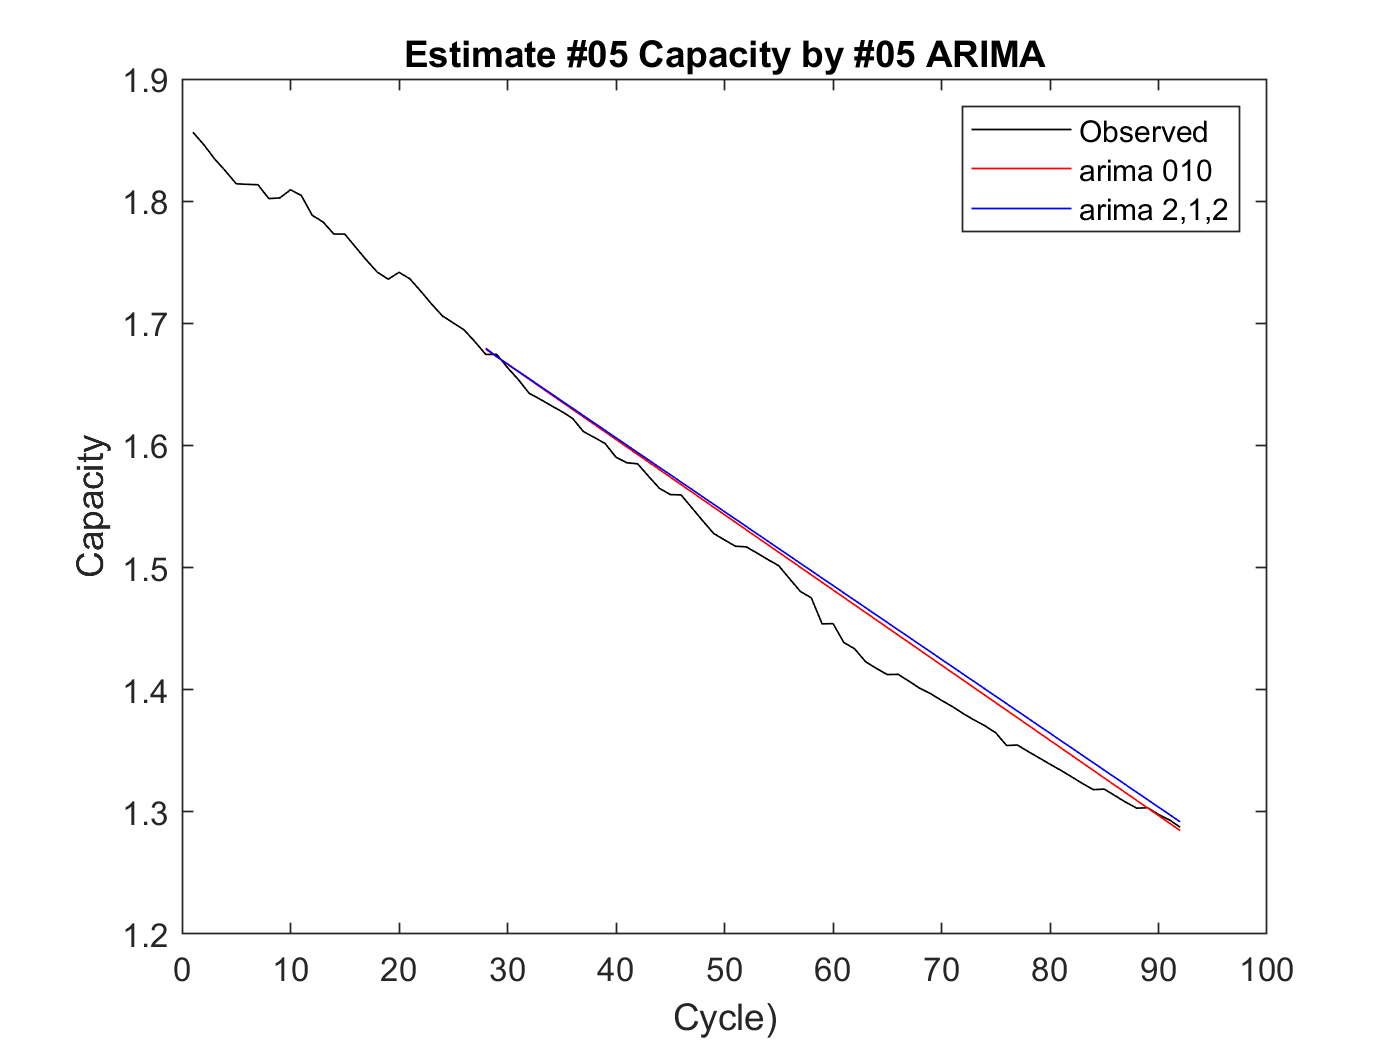




figure
plot(cap_05,'k');
hold on
plot([idx_0506_change:end_index],yf_05_base,'r');
plot([idx_0506_change:end_index],yf_05_opt,'b');
%plot([idx_0506_change:end_index],yf223,'g');
legend("Observed","arima 010", 'arima 2,1,2') %,"arima_223")
title("Estimate #05 Capacity by #05 ARIMA")
xlabel("Cycle)")
ylabel("Capacity")
hold off

# Estimate #06 Capacity by #06 ARIMA 

% battery 6 - arima 312
end_index = length(cap_06);
idx_change_before_vec = 1:idx_0605_change-1;
idx_change_vec = idx_0605_change:end_index;
change_length = length(idx_change_vec);

here aaa

% ARIMA 모델에 적당하다. PCF Die out PACF Die out 
Mdl_06_base = arima(0,1,0);
cap_06_pdq_string

cap_06_pdq_string = '3,1,2'

Mdl_06_opt = arima(3,1,2);  % 0 1 0

EstMdl_06_base = estimate(Mdl_06_base,yCap_06(idx_change_vec),'Y0',yCap_06(idx_change_before_vec));

 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    -0.0038891      0.0003207       -12.127      7.6184e-34
    Variance    6.2854e-06     5.9564e-08        105.52               0



EstMdl_06_opt = estimate(Mdl_06_opt,yCap_06(idx_change_vec),'Y0',yCap_06(idx_change_before_vec));

 
    ARIMA(3,1,2) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic     PValue  
                __________    _____________    __________    _________

    Constant    -0.0038891       0.013981        -0.27817      0.78088
    AR{1}                0         2.3326               0            1
    AR{2}                0         1.4268               0            1
    AR{3}            2e-12        0.13914      1.4374e-11            1
    MA{1}        -0.048645         2.3427       -0.020765      0.98343
    MA{2}          0.06979         1.3235        0.052734      0.95794
    Variance    6.1576e-06      1.404e-06          4.3857    1.156e-05




%yf_06_change_before = yCap_06(idx_change_before_vec(end - 1:end));
yf_06_change_before = yCap_06(idx_change_before_vec(1:end));

yf_06_base = forecast(EstMdl_06_base,change_length,yf_06_change_before);
yf_06_opt = forecast(EstMdl_06_opt,change_length,yf_06_change_before);


%Plot the first xxx observations and the forecasts.
EstMdl_06_base

EstMdl_06_base =   arima with properties:

     Description: "ARIMA(0,1,0) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 1
               D: 1
               Q: 0
        Constant: -0.00388907
              AR: {}
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 6.28536e-06

EstMdl_06_opt

EstMdl_06_opt =   arima with properties:

     Description: "ARIMA(3,1,2) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 4
               D: 1
               Q: 2
        Constant: -0.00388907
              AR: {2e-12} at lag [3]
             SAR: {}
              MA: {-0.0486455 0.0697904} at lags [1 2]
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 6.15761e-06

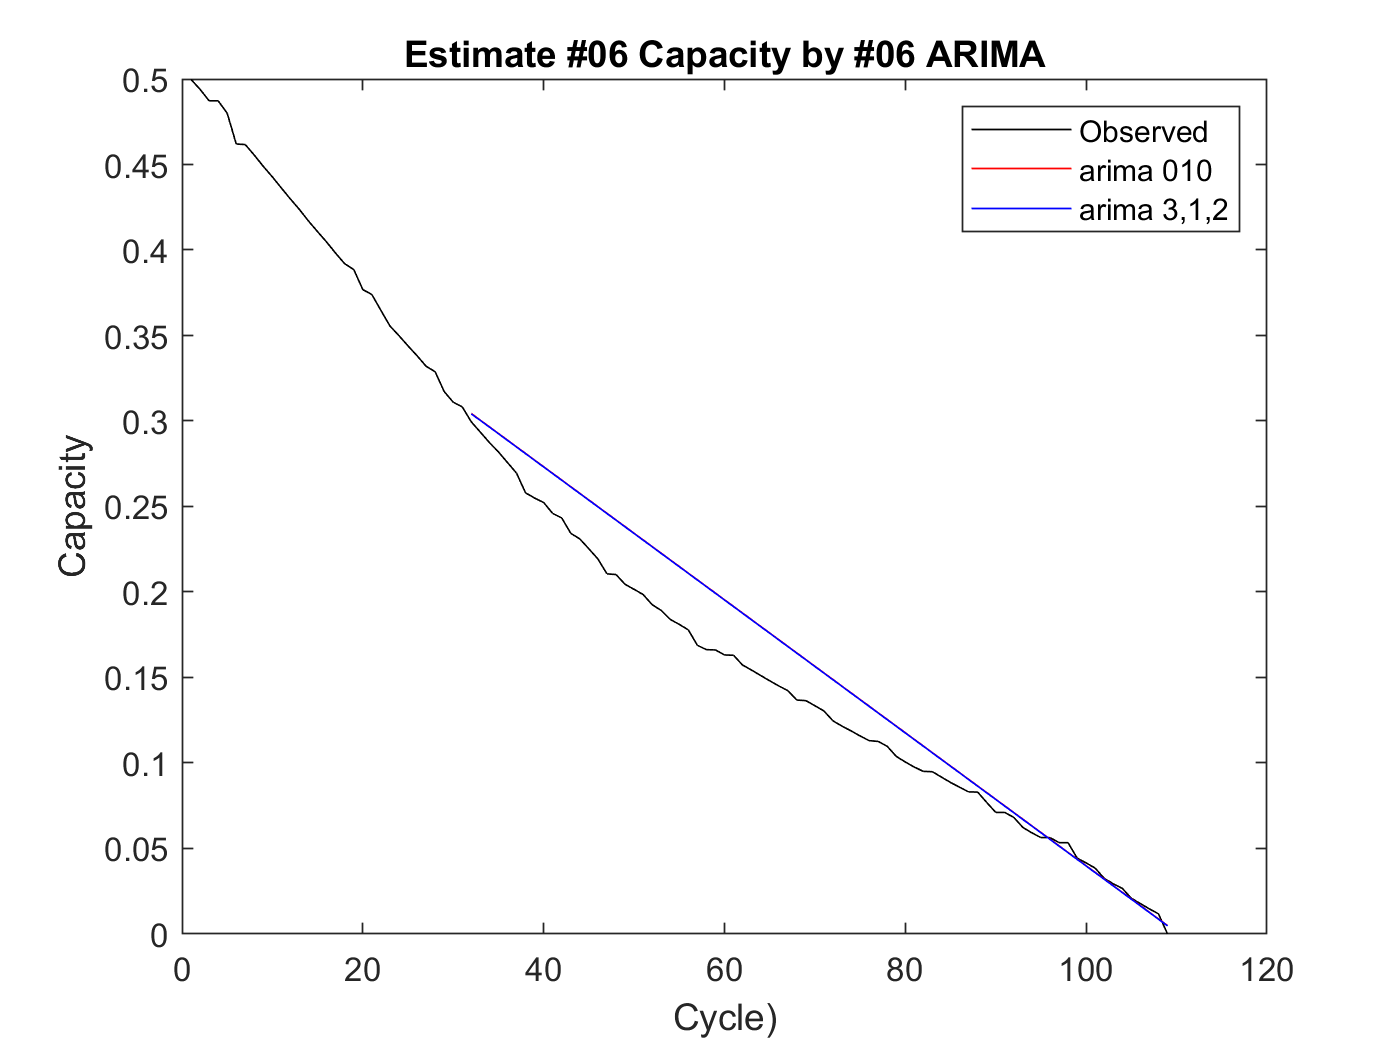


figure
plot(yCap_06,'k');
hold on
plot([idx_0605_change:end_index],yf_06_base,'r');
plot([idx_0605_change:end_index],yf_06_opt,'b');
legend("Observed","arima 010", 'arima 3,1,2')
title("Estimate #06 Capacity by #06 ARIMA")
xlabel("Cycle)")
ylabel("Capacity")
hold off

# Training Model - #0506

idx_change_vec = idx_0506_change-1;
end_index = length(cap_0506);

idx_change_before_vec = 1:idx_change_vec;
idx_change_vec = (idx_change_vec+1):end_index;
% ARIMA 모델에 적당하다. PCF Die out PACF Die out 
Mdl_0506_base = arima(0,1,0);
cap_0506_pdq_string

cap_0506_pdq_string = '3,1,2'

Mdl_0506_opt = arima(3,1,2);  
EstMdl_0506_base = estimate(Mdl_0506_base,cap_0506(idx_change_vec),'Y0',cap_0506(idx_change_before_vec));

 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant     -0.006783     0.00059187        -11.46      2.0911e-30
    Variance    1.9558e-05     2.6925e-06         7.264      3.7583e-13



EstMdl_0506_opt = estimate(Mdl_0506_opt,cap_0506(idx_change_vec),'Y0',cap_0506(idx_change_before_vec));

 
    ARIMA(3,1,2) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic      PValue  
                ___________    _____________    __________    __________

    Constant    -0.00020557     0.00014262        -1.4414        0.14947
    AR{1}            1.3466         0.1821         7.3946      1.418e-13
    AR{2}          -0.33327        0.30233        -1.1023        0.27032
    AR{3}         -0.046889        0.15085       -0.31084        0.75593
    MA{1}           -1.6941        0.11887        -14.251     4.4048e-46
    MA{2}           0.76267        0.12631         6.0381     1.5595e-09
    Variance     1.5919e-05     2.2296e-06           7.14     9.3343e-13




EstMdl_0506_base

EstMdl_0506_base =   arima with properties:

     Description: "ARIMA(0,1,0) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 1
               D: 1
               Q: 0
        Constant: -0.00678296
              AR: {}
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 1.9558e-05

EstMdl_0506_opt

EstMdl_0506_opt =   arima with properties:

     Description: "ARIMA(3,1,2) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 4
               D: 1
               Q: 2
        Constant: -0.000205568
              AR: {1.34658 -0.33327 -0.0468885} at lags [1 2 3]
             SAR: {}
              MA: {-1.69406 0.762675} at lags [1 2]
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 1.59192e-05

# Training Model - #0605

idx_change_vec = idx_0605_change-1;
end_index = length(cap_0605);

idx_change_before_vec = 1:idx_change_vec;
idx_change_vec = (idx_change_vec+1):end_index;
% ARIMA 모델에 적당하다. PCF Die out PACF Die out 
Mdl_0605_base = arima(0,1,0);
cap_0605_pdq_string

cap_0605_pdq_string = '2,1,1'

Mdl_0605_opt = arima(2,1,1);  
EstMdl_0605_base = estimate(Mdl_0605_base,cap_0605(idx_change_vec),'Y0',cap_0605(idx_change_before_vec));

 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    -0.0061146      0.0005386       -11.353      7.1866e-30
    Variance    1.5459e-05     1.7652e-06        8.7581      1.9856e-18



EstMdl_0605_opt = estimate(Mdl_0605_opt,cap_0605(idx_change_vec),'Y0',cap_0605(idx_change_before_vec));

 
    ARIMA(2,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic     PValue 
                __________    _____________    __________    ________

    Constant    -0.0020208      0.0033089       -0.61071      0.54139
    AR{1}          0.41194        0.48581        0.84796      0.39646
    AR{2}          0.25526        0.11923         2.1409     0.032279
    MA{1}         -0.57233        0.48429        -1.1818      0.23729
    Variance    1.4802e-05     1.8729e-06         7.9036     2.71e-15




EstMdl_0605_base

EstMdl_0605_base =   arima with properties:

     Description: "ARIMA(0,1,0) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 1
               D: 1
               Q: 0
        Constant: -0.00611462
              AR: {}
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 1.54594e-05

EstMdl_0605_opt

EstMdl_0605_opt =   arima with properties:

     Description: "ARIMA(2,1,1) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 3
               D: 1
               Q: 1
        Constant: -0.0020208
              AR: {0.411943 0.255259} at lags [1 2]
             SAR: {}
              MA: {-0.572332} at lag [1]
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 1.48024e-05

# Estimate #0506 Capacity by #0506 ARIMA 

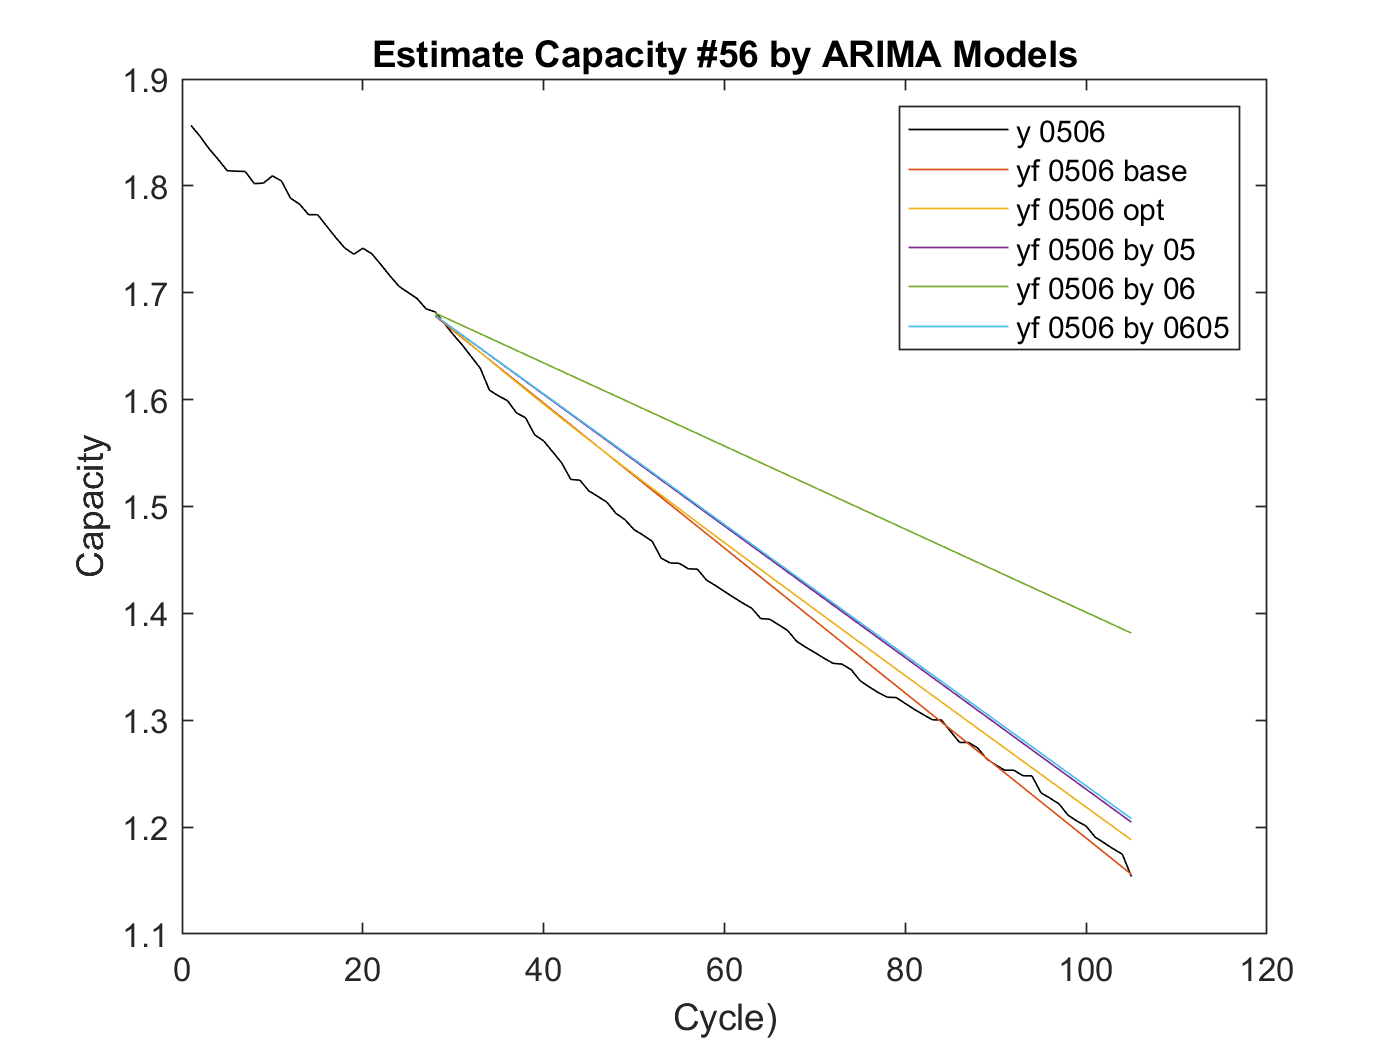

idx_change_vec = idx_0506_change-1;
change_length = length(cap_0506) - idx_change_vec;
end_index = length(cap_0506);
idx_change_before_vec = 1:idx_change_vec;

%yf_0506_change_before = cap_0506(idx_change_before_vec(end - 1:end)); % error - Y0 at least 4
yf_0506_change_before = cap_0506(idx_change_before_vec(1:end)); 
yf_0506_base = forecast(EstMdl_0506_base,change_length,yf_0506_change_before);
yf_0506_opt = forecast(EstMdl_0506_opt,change_length,yf_0506_change_before);
yf_0506_by_05 = forecast(EstMdl_05_base,change_length,yf_0506_change_before);
yf_0506_by_06 = forecast(EstMdl_06_base,change_length,yf_0506_change_before);
yf_0506_by_0605 = forecast(EstMdl_0605_base,change_length,yf_0506_change_before);

figure
plot(cap_0506,'k');
hold on
plot([idx_0506_change:end_index],yf_0506_base);
plot([idx_0506_change:end_index],yf_0506_opt);
plot([idx_0506_change:end_index],yf_0506_by_05);
plot([idx_0506_change:end_index],yf_0506_by_06);
plot([idx_0506_change:end_index],yf_0506_by_0605);
legend('y 0506','yf 0506 base','yf 0506 opt','yf 0506 by 05','yf 0506 by 06','yf 0506 by 0605')
title("Estimate Capacity #56 by ARIMA Models")
xlabel("Cycle)")
ylabel("Capacity")
hold off

# Estimate #0605 Capacity by #0605 ARIMA 

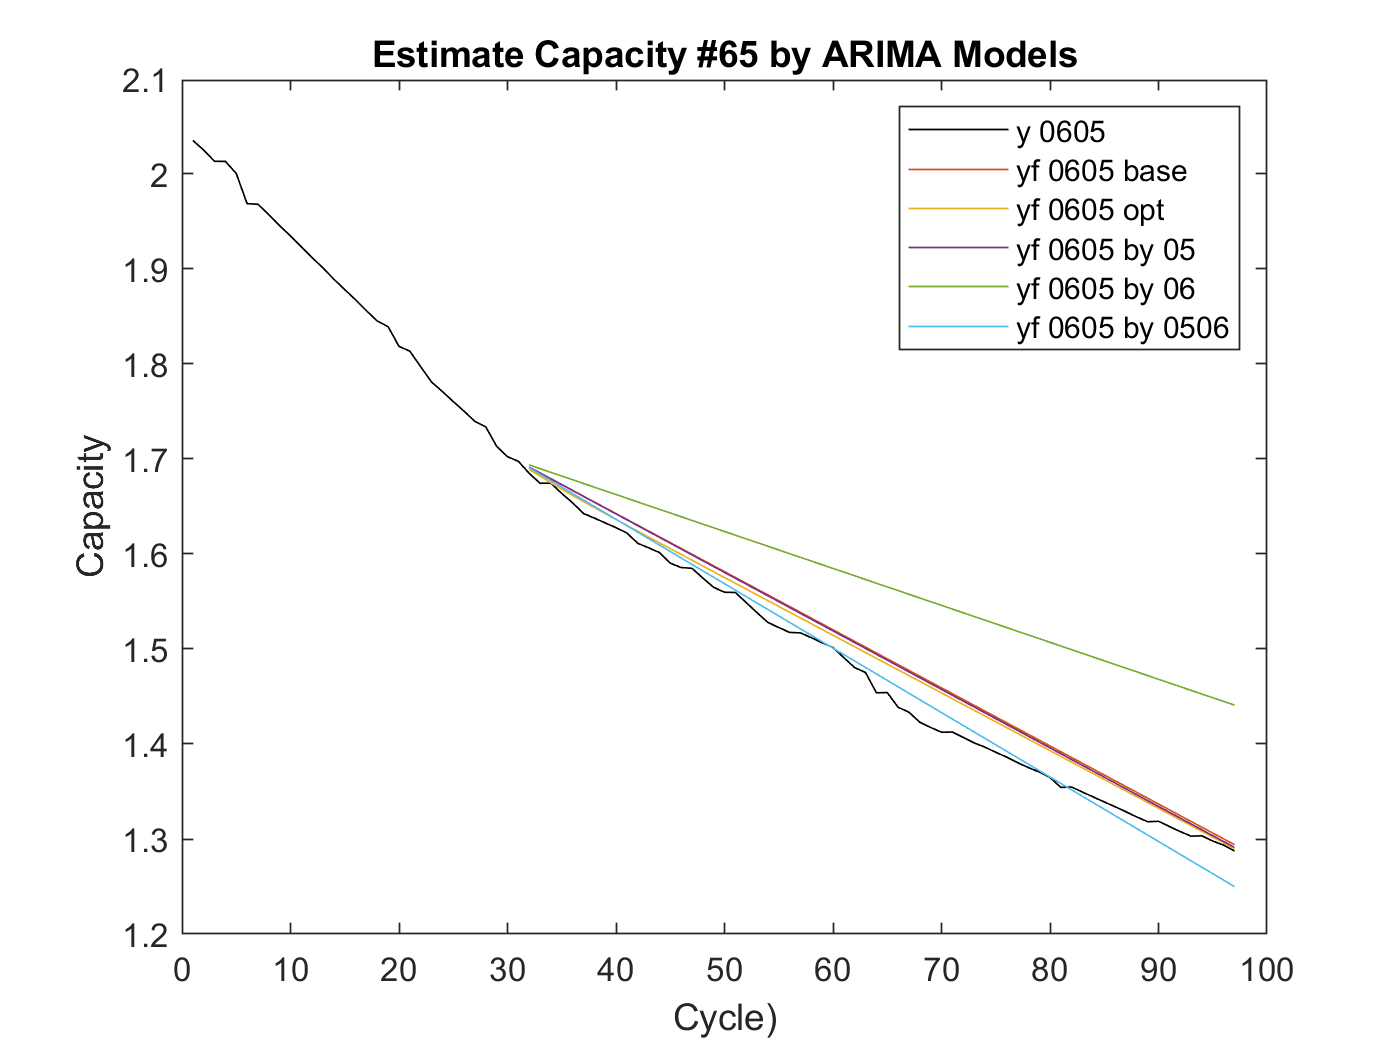

% battery 65 - arima 313

%result_05_06_patten_change = [27 31];
%result_06_05_patten_change = [30 27];

% to get EstMdl_0605_base to use 56
idx_change_vec = idx_0605_change-1;
change_length = length(cap_0605) - idx_change_vec;
end_index = length(cap_0605);

idx_change_before_vec = 1:idx_change_vec;
idx_change_vec = (idx_change_vec+1):end_index;
% ARIMA 모델에 적당하다. PCF Die out PACF Die out 

%yf_0506_change_before = cap_0605(idx_change_before_vec(end - 1:end)); % error - Y0 at least 4
yf_0605_change_before = cap_0605(idx_change_before_vec(1:end)); 
yf_0605_base = forecast(EstMdl_0605_base,change_length,yf_0605_change_before);
yf_0605_opt = forecast(EstMdl_0605_opt,change_length,yf_0605_change_before);
yf_0605_by_05 = forecast(EstMdl_05_base,change_length,yf_0605_change_before);
yf_0605_by_06 = forecast(EstMdl_06_base,change_length,yf_0605_change_before);
yf_0605_by_0506 = forecast(EstMdl_0506_base,change_length,yf_0605_change_before);


figure
plot(cap_0605,'k');
hold on
plot([idx_0605_change:end_index],yf_0605_base);
plot([idx_0605_change:end_index],yf_0605_opt);
plot([idx_0605_change:end_index],yf_0605_by_05);
plot([idx_0605_change:end_index],yf_0605_by_06);
plot([idx_0605_change:end_index],yf_0605_by_0506);
title("Estimate Capacity #65 by ARIMA Models")
legend('y 0605','yf 0605 base','yf 0605 opt','yf 0605 by 05','yf 0605 by 06','yf 0605 by 0506')
xlabel("Cycle)")
ylabel("Capacity")
hold off

RMSE

size(cap_0605(idx_0605_change:end))

ans =     66     1


size(yf_0605_by_05)

ans =     66     1



%{
RMSE_5_by_05 = sqrt(mean(( cap_05' - yf_05_opt' ).^2))
RMSE_6_by_06 = sqrt(mean(( yCap_06' - yf_06_opt' ).^2))
RMSE_56_by_05 = sqrt(mean(( cap_0506' - yf_0506_by_05 ).^2))
RMSE_56_by_06 = sqrt(mean(( cap_0506' - yf_0506_by_06 ).^2))
RMSE_65_by_05 = sqrt(mean(( cap_0605' - yf_0605_by_05 ).^2))
RMSE_65_by_06 = sqrt(mean(( cap_0605' - yf_0605_by_06 ).^2))
%}


RMSE_56_by_05 = sqrt(mean(( cap_0506(idx_0506_change:end) - yf_0506_by_05 ).^2))

RMSE_56_by_05 = 0.0479

RMSE_56_by_06 = sqrt(mean(( cap_0506(idx_0506_change:end) - yf_0506_by_06 ).^2))

RMSE_56_by_06 = 0.1450


RMSE_65_by_05 = sqrt(mean(( cap_0605(idx_0605_change:end) - yf_0605_by_05 ).^2))

RMSE_65_by_05 = 0.0259

RMSE_65_by_06 = sqrt(mean(( cap_0605(idx_0605_change:end) - yf_0605_by_06 ).^2))

RMSE_65_by_06 = 0.1099